# **Circuitos Electricos II**

**Roberto Sanchez Figueroa**

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  ***[***https://github.com/brrsanchezfi/Circuitos_2022_1***](https://github.com/brrsanchezfi/Circuitos_2022_1)

# **Soluciones propuestas para los ejercicios del taller 4**

## 1.Analisis por Matlab symbolic

####     Circuito Y-D

El siguiente metodo es la solucion que considero mas facil a la hora de entender el circuito.

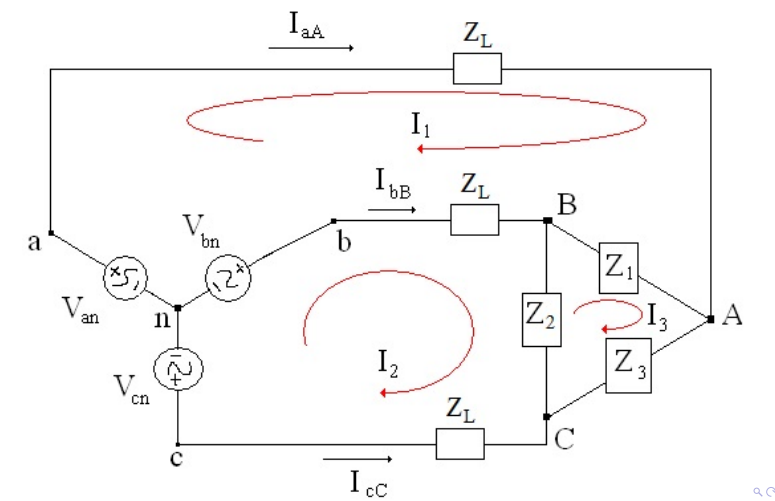

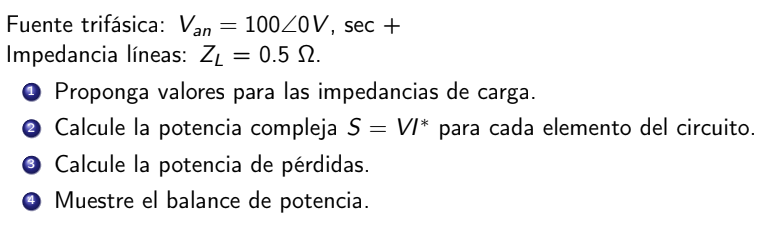

Voltaje = 100;

    %{  
    La funcion "pol_com(magnitud,angulo)" convierte un fasor a rectangular
    por medio de la identidad de euler
    %}

V_an_x = pol_com(Voltaje/sqrt(2),0);   
V_bn_x = pol_com(Voltaje/sqrt(2),-120);
V_cn_x = pol_com(Voltaje/sqrt(2),120);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%1. En estos blocks proporcionamos los valores de impedancia

Z1_x = 8+7i;
Z2_x = 6+3i;
Z3_x = 5+5i;

Z_L_x = 0.5;

syms I1 I2 I3 Z_L V_an V_bn V_cn Z1 Z2 Z3   

Sys = [V_an - V_bn == Z_L*(I1) + Z1*(I1-I3) + Z_L*(I1-I2); 
       V_bn - V_cn == Z_L*(I2-I1) + Z2*(I2-I3) + Z_L*(I2);
       0 == Z1*(I3-I1) + Z2*(I3-I2) + Z3*(I3)]

$$Sys = \left(\begin{array}{c} V_{\mathrm{an}}-V_{\mathrm{bn}}=I_{1}\,Z_{L}+Z_{1}\,\left(I_{1}-I_{3}\right)+Z_{L}\,\left(I_{1}-I_{2}\right)\\ V_{\mathrm{bn}}-V_{\mathrm{cn}}=I_{2}\,Z_{L}+Z_{2}\,\left(I_{2}-I_{3}\right)-Z_{L}\,\left(I_{1}-I_{2}\right)\\ 0=I_{3}\,Z_{3}-Z_{1}\,\left(I_{1}-I_{3}\right)-Z_{2}\,\left(I_{2}-I_{3}\right) \end{array}\right)$$


Sol = solve(Sys,[I1, I2, I3]);

I1 = Sol.I1   %reescribo la variable I1,I2,I3 con el nuevo valor simbolico

$$I1 = -\frac{V_{\mathrm{bn}}\,Z_{2}\,Z_{3}-V_{\mathrm{an}}\,Z_{2}\,Z_{3}-V_{\mathrm{an}}\,Z_{1}\,Z_{2}+V_{\mathrm{cn}}\,Z_{1}\,Z_{2}-2\,V_{\mathrm{an}}\,Z_{1}\,Z_{L}-2\,V_{\mathrm{an}}\,Z_{2}\,Z_{L}-2\,V_{\mathrm{an}}\,Z_{3}\,Z_{L}+V_{\mathrm{bn}}\,Z_{1}\,Z_{L}+V_{\mathrm{bn}}\,Z_{2}\,Z_{L}+V_{\mathrm{bn}}\,Z_{3}\,Z_{L}+V_{\mathrm{cn}}\,Z_{1}\,Z_{L}+V_{\mathrm{cn}}\,Z_{2}\,Z_{L}+V_{\mathrm{cn}}\,Z_{3}\,Z_{L}}{3\,Z_{1}\,{Z_{L}}^{2}+3\,Z_{2}\,{Z_{L}}^{2}+3\,Z_{3}\,{Z_{L}}^{2}+Z_{1}\,Z_{2}\,Z_{3}+2\,Z_{1}\,Z_{2}\,Z_{L}+2\,Z_{1}\,Z_{3}\,Z_{L}+2\,Z_{2}\,Z_{3}\,Z_{L}}$$

I2 = Sol.I2;
I3 = Sol.I3;

%CORRIENTES DE MALLAS

I1 = subs(I1,[V_an V_bn V_cn Z1 Z2 Z3 Z_L],[V_an_x V_bn_x V_cn_x Z1_x Z2_x Z3_x Z_L_x]);
I2 = subs(I2,[V_an V_bn V_cn Z1 Z2 Z3 Z_L],[V_an_x V_bn_x V_cn_x Z1_x Z2_x Z3_x Z_L_x]);
I3 = subs(I3,[V_an V_bn V_cn Z1 Z2 Z3 Z_L],[V_an_x V_bn_x V_cn_x Z1_x Z2_x Z3_x Z_L_x]);

%CORRIENTES DE LINEAS

I_aA = I1;        
I_bB = I2 - I1;   
I_cC = -I2;       

%convertimos las variables simbolicas a una de tipo numero

I_aA = double(I_aA)

I_aA = 16.0506 - 14.9532i

I_bB = double(I_bB)

I_bB = -15.9733 - 12.9620i

I_cC = double(I_cC)

I_cC = -0.0772 + 27.9152i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%2. Calcule la potencia compleja

    %Para hallar las potencias complejas usamos la formula suministrada en el
    %ununciado, omito la demostracion del por que el conjugado (dogma de fe)

S_a = V_an_x*conj(I_aA)      %potencia entragada por las fuentes

S_a = 1.1349e+03 + 1.0574e+03i

S_b = V_bn_x*conj(I_bB)

S_b = 1.3585e+03 + 5.1989e+02i

S_c = V_cn_x*conj(I_cC)

S_c = 1.7122e+03 + 9.8222e+02i


S = round(S_a+S_b+S_c, 0)    %Potencia total compleja redondeada

S = 4.2060e+03 + 2.5590e+03i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%3. Calcule la potencia de perdidas, aplicamos ley ohm para impedancias y
%aplicamos ley watt 

S_ZL = round(Z_L_x * (abs(I_aA^2) + abs(I_bB^2)+ abs(I_cC^2)),0)    %potencia perdida por la resistencia de linea

S_ZL = 842


%CORRIENTES DE CARGA

I_Z1 = double(I1-I3);
I_Z2 = double(I2-I3);
I_Z3 = double(I3);

S_Z1 = abs(I_Z1*I_Z1)*Z1_x;
S_Z2 = abs(I_Z2*I_Z2)*Z2_x;
S_Z3 = abs(I_Z3*I_Z3)*Z3_x;

S_Z_carga = round(S_Z1+S_Z2+S_Z3)     %potencia consumida por la cargas

S_Z_carga = 3.3640e+03 + 2.5590e+03i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%4. Balance de potencia


Balance = round(S_ZL + S_Z_carga - S, 0) 

Balance = 0

#### Simulacion

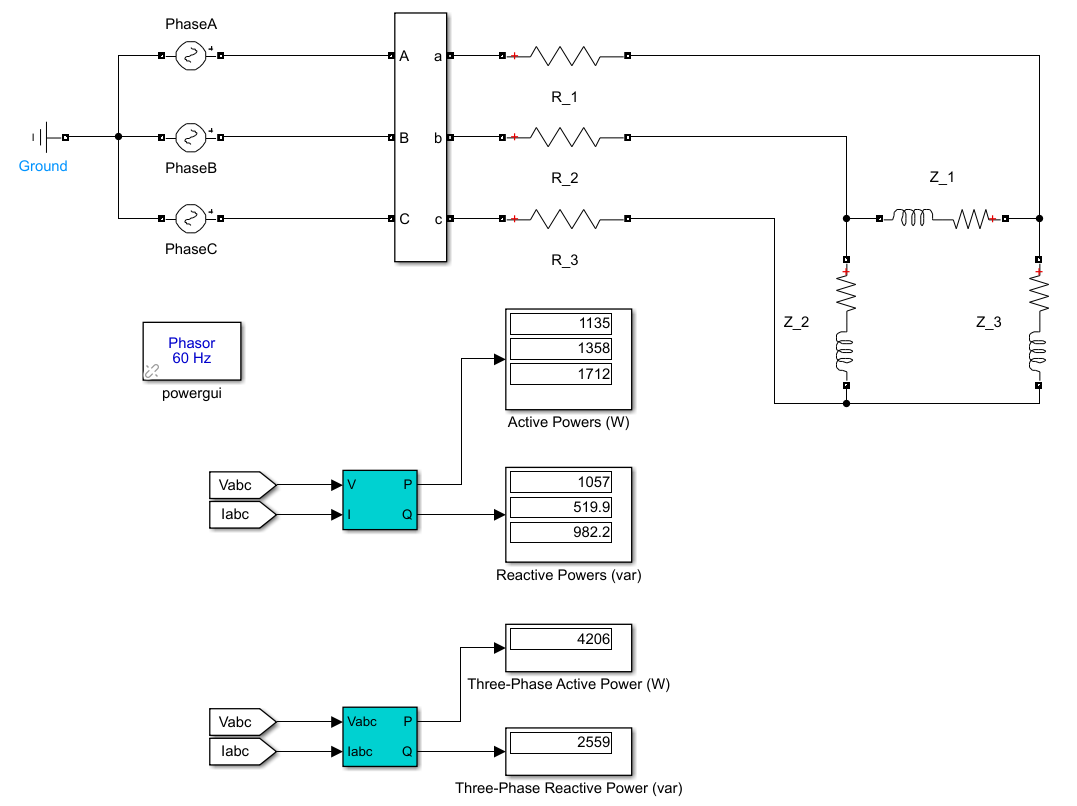

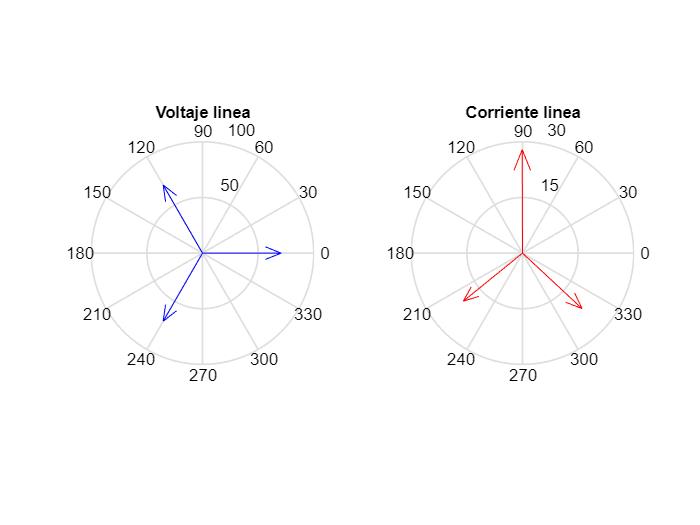

%herramienta interesante

tiledlayout(1,2)
ax1 = nexttile;
compass(ax1,[V_an_x V_bn_x V_cn_x],'b')
title(ax1,'Voltaje linea')
ax2 = nexttile;
compass(ax2,[I_aA I_bB I_cC],'r')
title(ax2,'Corriente linea')


% hold off




## 2.Analisis por determinantes(Cramer) y metodo de Aron (2 vatimeros)

####     Circuito Y-Y

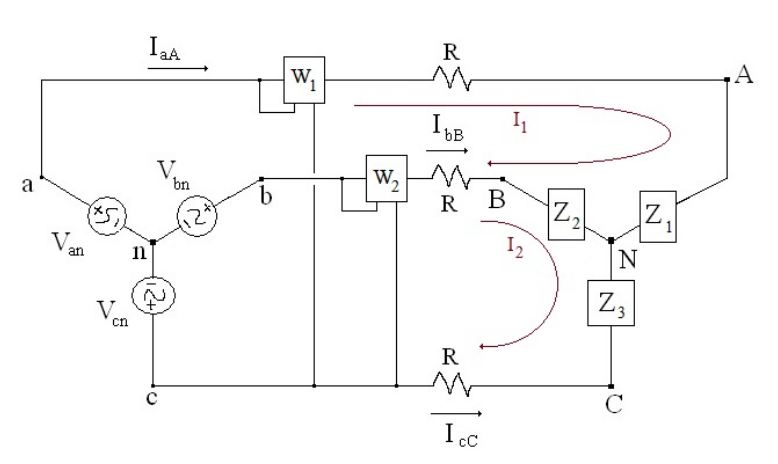

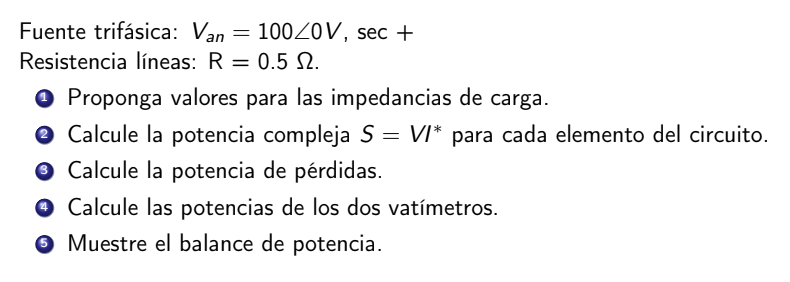

Voltaje = 100;

V_an = pol_com(Voltaje/sqrt(2),0);     %Valores RMS
V_bn = pol_com(Voltaje/sqrt(2),-120);
V_cn = pol_com(Voltaje/sqrt(2),120);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%1. En estos blocks proporcionamos los valores de impedancia

Z1 = 5+5i;
Z2 = 5+5i;
Z3 = 5+5i;

R = 0.5;


M_1=[(R+Z1+Z2+R); -(R+Z2)]       %impedancia malla 1

M_1 =   11.0000 +10.0000i
  -5.5000 - 5.0000i



M_2=[-(R+Z2); (R+Z2+Z3+R)]       %impedancia malla 2

M_2 =   -5.5000 - 5.0000i
  11.0000 +10.0000i



M_V=[(V_an-V_bn); (V_bn-V_cn)]   %Voltajes

M_V = 	1.0e+02 *

   1.0607 + 0.6124i
   0.0000 - 1.2247i



%DETERMINANTES

DM_1_2=det([M_1,M_2]);      %  det
DM_V_2=det([M_V,M_2]);      %  I1
DM_1_V=det([M_1,M_V]);      %  I2


%CORRIENTE DE MALLA

I=[(DM_V_2/DM_1_2);(DM_1_V/DM_1_2)];
I1=I(1,1)

I1 = 7.0391 - 6.3992i

I2=I(2,1)

I2 = -2.0223 - 9.2956i



%CORRIENTE DE LINEA

I_aA = I1

I_aA = 7.0391 - 6.3992i

I_bB = I2- I1

I_bB = -9.0614 - 2.8964i

I_cC = -I2

I_cC = 2.0223 + 9.2956i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%2. Calcule la potencia compleja

S_a = V_an*conj(I_aA);       
S_b = V_bn*conj(I_bB);
S_c = V_cn*conj(I_cC);

S = round(S_a+S_b+S_c, 0)

S = 1.4930e+03 + 1.3570e+03i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%3. Calcule la potencia de perdidas, aplicamos ley ohm para impedancias y
%aplicamos ley watt 

S_R = round(R * (abs(I_aA^2) + abs(I_bB^2)+ abs(I_cC^2)),0)    %potencia perdida por la resistencia de linea

S_R = 136


%CORRIENTES DE CARGA

I_Z1 = double(I1);
I_Z2 = double(I2-I1);
I_Z3 = double(-I2);

S_Z1 = abs(I_Z1*I_Z1)*Z1;
S_Z2 = abs(I_Z2*I_Z2)*Z2;
S_Z3 = abs(I_Z3*I_Z3)*Z3;

S_Z_carga = round(S_Z1+S_Z2+S_Z3)     %potencia consumida por la cargas

S_Z_carga = 1.3570e+03 + 1.3570e+03i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%4. Calcule la potencia de los dos vatimetros




$$\begin{array}{l}
P_{\textrm{total}} =P_{\textrm{w1}} +P_{\textrm{w2}} \\
P_{\textrm{w1}} \;\;=P_{\textrm{fase}-\textrm{fase}} \cdot \textrm{conj}\left(I_{\textrm{linea}} \right)
\end{array}$$


W1 = (V_an-V_cn)*conj(I_aA)

W1 = 1.1385e+03 + 2.4768e+02i


W2 = (V_bn-V_cn)*conj(I_bB)

W2 = 3.5474e+02 + 1.1098e+03i


W_total = (W1 + W2)

W_total = 1.4932e+03 + 1.3575e+03i


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%5. Balance de cargas

Balance = round(S_R + S_Z_carga - S, 0) 

Balance = 0

Simulacion

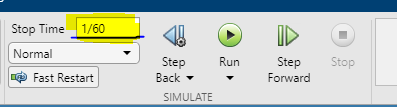

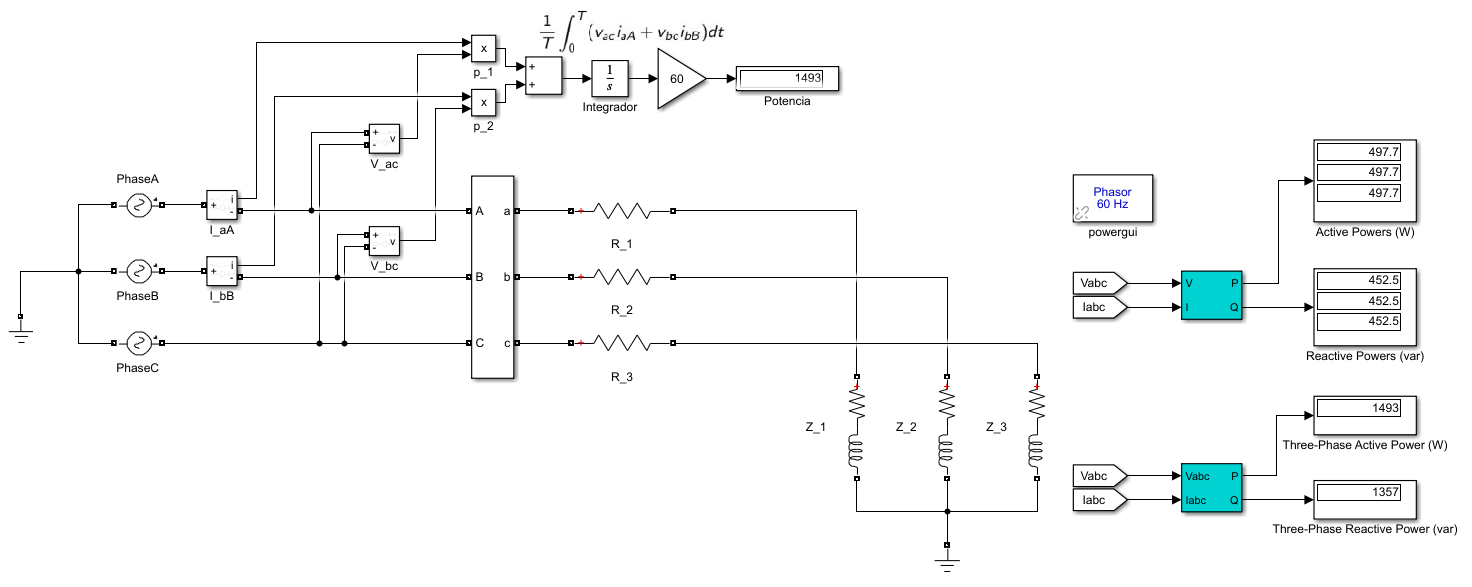

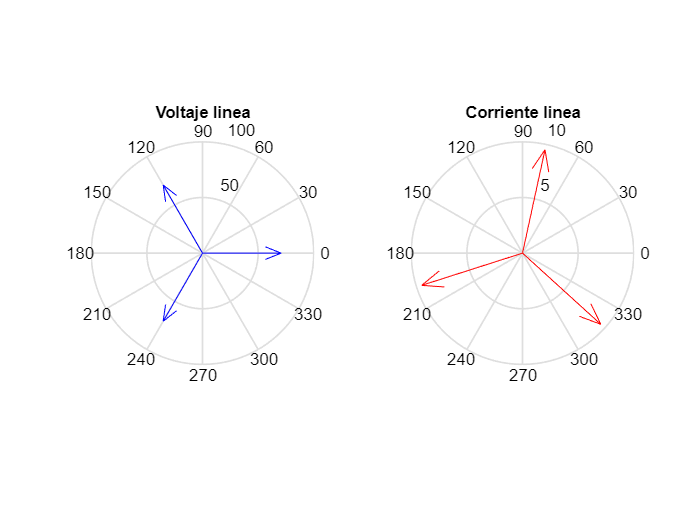

%herramienta interesante

tiledlayout(1,2)
ax1 = nexttile;
compass(ax1,[V_an V_bn V_cn],'b')
title(ax1,'Voltaje linea')
ax2 = nexttile;
compass(ax2,[I_aA I_bB I_cC],'r')
title(ax2,'Corriente linea')

## 3.Demostracion

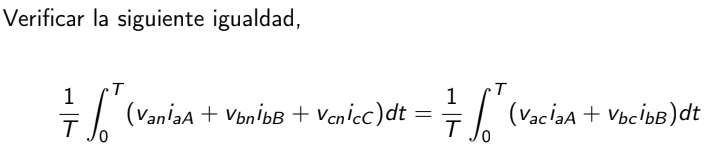

function Complejo = pol_com(M,A)  % magnitud, angulo

Complejo = M * exp (deg2rad (A) * 1i); 

end